#                                 ROS 2 Node - Webcam

## Create a ROS2 Node

node = ros2node('NodeWebcam');
%ros2 generate tge topic to send the data to camera


Specify an execution rate for running the ROS 2 node

rate = ros2rate(node,5); % Desired rate = 5 Hz
cam = webcam(1);

Load of pretrained Object detector

det = yolov4ObjectDetector('csp-darknet53-coco');

Print

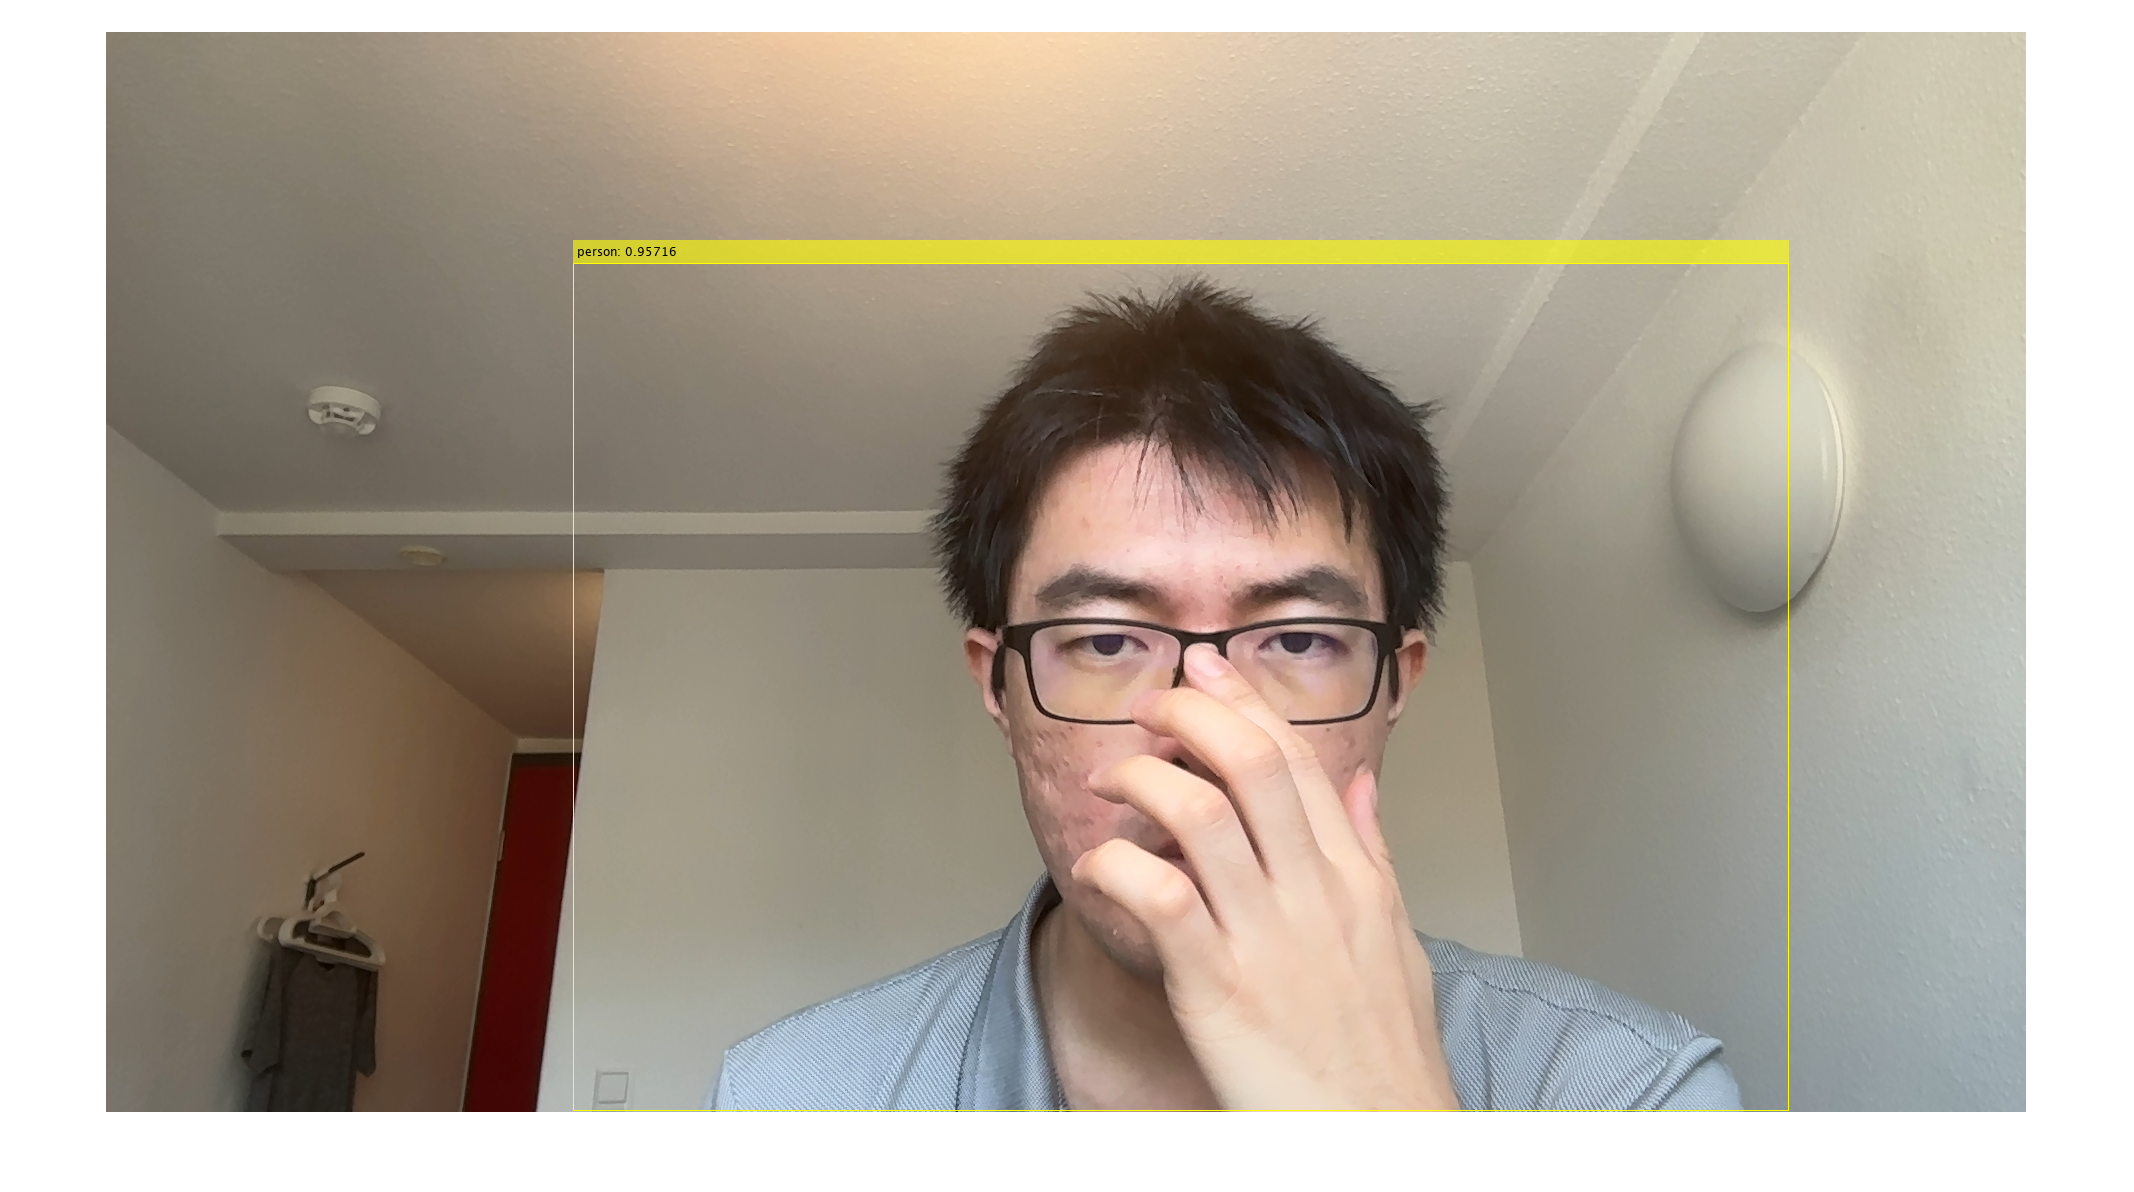

reset(rate)
for i = 1:100
    image = snapshot(cam);
    [bboxes, scores, labels] = detect(det, image);
    annotations = string(labels) + ': ' + string(scores);
    image = insertObjectAnnotation(image, 'rectangle', bboxes, annotations);
    imshow(image);
    waitfor(rate);
end